syms z Y n X
% X = ztrans(kroneckerDelta(n));
X1 = z^-1*X;
X2 = z^-2*X;
Y1 = z^-1*Y;
Y2 = z^-2*Y;
G = -Y + 1.6*Y1 - 0.8*Y2 + 0.01*X + 0.03*X1 + 0.015*X2

$$G = \frac{X}{100}-Y+\frac{3\,X}{100\,z}+\frac{3\,X}{200\,z^{2}}+\frac{8\,Y}{5\,z}-\frac{4\,Y}{5\,z^{2}}$$

SOL = solve(G,Y)

$$SOL = \frac{2\,X\,z^{2}+6\,X\,z+3\,X}{200\,z^{2}-320\,z+160}$$

H = simplify(SOL/X)

$$H = \frac{2\,z^{2}+6\,z+3}{40\,\left(5\,z^{2}-8\,z+4\right)}$$

n = [2 6 3]

n =      2     6     3


d = [200 -320 160]

d =    200  -320   160


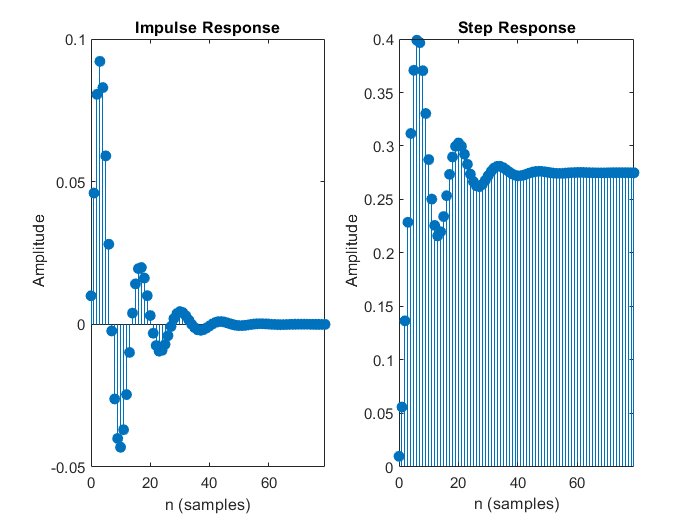

figure
subplot(1,2,1)
impz(n,d,80)
subplot(1,2,2)
stepz(n,d,80)